PointsVAH_U = [333 300 283 268 250 225 215.5]

PointsVAH_U =   333.0000  300.0000  283.0000  268.0000  250.0000  225.0000  215.5000


PointsVAH_I = [0   50  100 150 225 375 450]

PointsVAH_I =      0    50   100   150   225   375   450





p = polyfit(PointsVAH_I,PointsVAH_U,3)

p =    -0.0000    0.0014   -0.6087  330.9789


Iout = 0:PointsVAH_I(end)

Iout =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


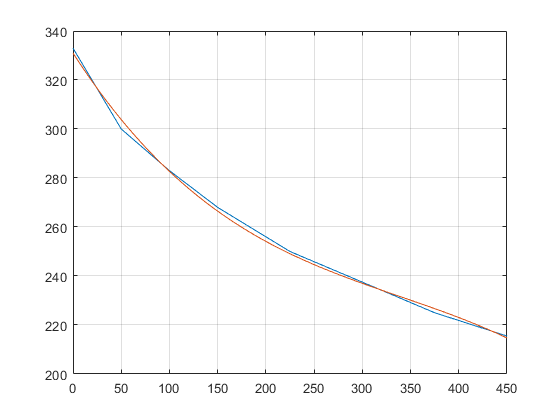

Uout = polyval(p,Iout);

plot(PointsVAH_I,PointsVAH_U)
grid on
hold on
plot(Iout,Uout)
hold off


for i=2:length(PointsVAH_U)
   du = abs(PointsVAH_U(i) - PointsVAH_U(i-1));
   di = abs(PointsVAH_I(i) - PointsVAH_I(i-1));
   r = du/di
end

r = 0.6600

r = 0.3400

r = 0.3000

r = 0.2400

r = 0.1667

r = 0.1267


Rout = zeros(1,length(Uout)-1)

Rout =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pout = zeros(1,length(Uout)-1)

Pout =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


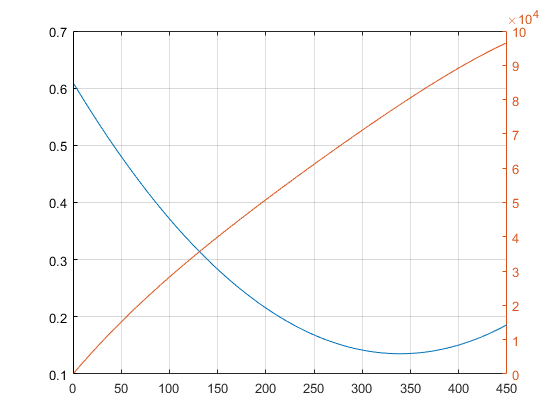

for i=2:length(Uout)
   du = Uout(i) - Uout(i-1);
   di = Iout(i) - Iout(i-1);
   Rout(i-1) = abs(du/di);
   Pout(i-1) = Uout(i) * Iout(i);
end

plot(Iout(2:end),Rout)
grid on
hold on
yyaxis right
plot(Iout(2:end),Pout)
hold off